## Voltage divider using resistors

circuit = Circuit('circuits/passive/c1_voltage_divider.txt');
circuit.list

ans =     'Vin 1 0 DC 5
     R1 1 2 1000
     R2 2 0 3000
     '


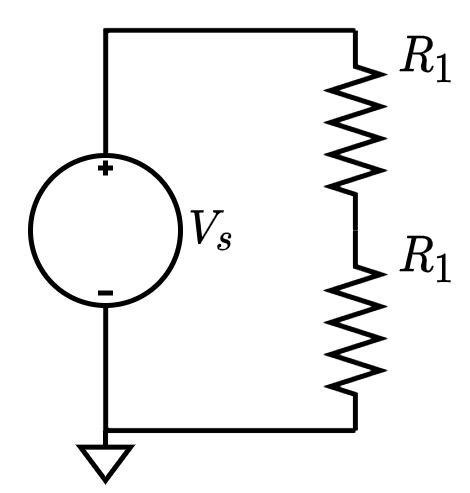

ELAB.analyze(circuit)

Symbolic analysis successful (0.403481 sec).


Maybe you want expressions for node voltages.

circuit.symbolic_node_voltages

$$ans = \left(\begin{array}{c} v_{1}=\mathrm{Vin}\\ v_{2}=\frac{R_{2}\,\mathrm{Vin}}{R_{1}+R_{2}} \end{array}\right)$$

Or the numerical currents for all elements in this particular circuit.

ELAB.evaluate(circuit)


Numerical evaluation successful (0.0949674 sec).


circuit.numerical_element_currents

$$ans = \left(\begin{array}{c} i_{\mathrm{R1}}=\frac{1}{800}\\ i_{\mathrm{R2}}=\frac{1}{800} \end{array}\right)$$

circuit.file_name

ans = 'circuits/passive/c1_voltage_divider.txt'